clc;

%======== Define global structs for options and ODE options 
global opts;
global ODEopts;
                        
%======== SET OPTIONS (see README.md for description) ========
opts = struct(  'debug', 0, ...                 
                'slopethresh', 0.01, ...         
                'exprthresh', 0.2, ...
                'splinesmoothing', 1.0, ...
                'spatialsmoothing', 0.5, ...
                'minborder_expr_ratio', 0.01, ...
                'Rld_method', 'slope_nodiff', ...
                'Rld_tsafety', 3, ...
                'synthesisfunction', 'synthesis_heaviside', ...
                'ODEAbsTol', 1e-4, ...
                'ODEsolver', 'ode45');

%======== set up ODE options 
ODEopts = odeset('AbsTol', opts.ODEAbsTol);

%======== SETUP GENE REGULATORY NETWORK PARAMETERS IN grn STRUCT ========
grn.Tgg     = [0.1   -1 ;  -1    0.1];     % Regulatory coefficients
grn.hg      = [0.5       0.5]';        % Thresholds/biases
grn.Rg      = [1           1]';           % Maximum synthesis rates
grn.lambdag = [1           1]';           % Degradation rates
grn.Dg      = [0           0 ]';          % Diffusion coefficients
xmax        = grn.Rg./grn.lambdag;        % maximum possible
                                          % expression
                                          
%======== SETUP TIMEPOINTS tt ========
tt = [0 : 0.05: 10];  % Time points 

%======== SETUP INITIAL CONDITIONS xntg(:,1,:) ========
numNuclei     = 1;      % number of nuclei and/or experimental conditions
numTimepoints = 201;     % number of timepoints (= numel (tt))
numGenes      = 2;      % number of genes
xntg          = NaN (numNuclei,numTimepoints,numGenes); % allocate array
xntg(:,1,:)   = [0.05  0.19];                             % initial conditions

%======== COMPUTE TRAJECTORIES xntg ========
[xntg] = computeTrajs (opts, grn, xntg, tt);

%======== INFER GRN PARAMETERS grnFIGR to get yntg
[grnFIGR, diagnostics] = infer (opts, xntg, tt, numGenes);

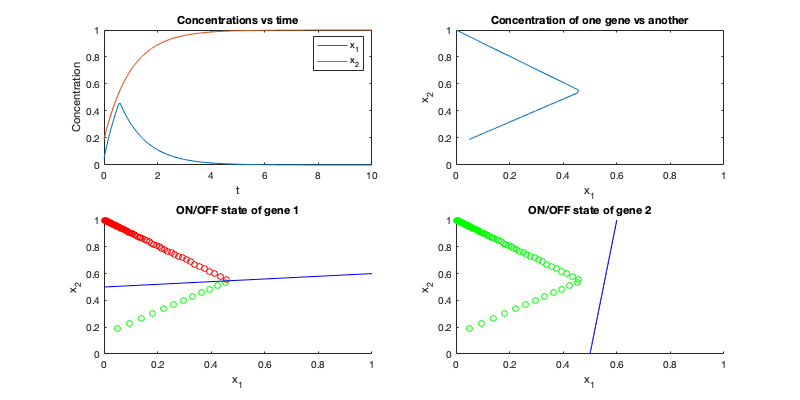

yntg = diagnostics.yntg;

% For plotting the decision boundaries for each gene
x1 = [0: 0.01*xmax(1): xmax(1)]';
g1_bdry_x2 = (-1.0*grn.hg(1)*ones(101,1) - grn.Tgg(1,1)*x1)/grn.Tgg(1,2);
g2_bdry_x2 = (-1.0*grn.hg(2)*ones(101,1) - grn.Tgg(2,1)*x1)/grn.Tgg(2,2);

% The points where each gene is ON or OFF
xntg_g1_on = xntg(:, yntg(:,:,1) > 0 , :);
xntg_g1_off = xntg(:, yntg(:,:,1) < 0 , :);
xntg_g2_on = xntg(:, yntg(:,:,2) > 0 , :);
xntg_g2_off = xntg(:, yntg(:,:,2) < 0 , :);


%======== VISUALIZE RESULTS
close all;
set (gcf, 'Position', [0 0 800 400]);

%-------- PLOT TRAJECTORIES x1(t) AND x2(t) --------
subplot (2, 2, 1); 
plot (tt, squeeze(xntg(1,:,:))); 
ylim([0,max(xmax)]);
xlabel ('t'); 
ylabel('Concentration'); 
legend ('x_1', 'x_2');
title('Concentrations vs time');

%-------- PLOT TRAJECTORIES x1(t) AND x2(t) --------
subplot (2, 2, 2); 
plot (xntg(:,:,1), xntg(:,:,2));
xlim([0,xmax(1)]);
ylim([0,xmax(2)]);
xlabel ('x_1'); 
ylabel('x_2'); 
title('Concentration of one gene vs another');


%-------- PLOT TRAJECTORIES IN (x1,x2) PLANE --------
subplot (2, 2, 3); hold on;
scatter (xntg_g1_on(1,:,1), xntg_g1_on(1,:,2), 'g'); xlabel ('x_1'); ylabel ('x_2');
scatter (xntg_g1_off(1,:,1), xntg_g1_off(1,:,2), 'r'); xlabel ('x_1'); ylabel ('x_2');
xlim([0,xmax(1)]);
ylim([0,xmax(2)]);
plot(x1, g1_bdry_x2, 'b');
title('ON/OFF state of gene 1');

subplot (2, 2, 4); hold on;
scatter (xntg_g2_on(1,:,1), xntg_g2_on(1,:,2), 'g'); xlabel ('x_1'); ylabel ('x_2');
scatter (xntg_g2_off(1,:,1), xntg_g2_off(1,:,2), 'r'); xlabel ('x_1'); ylabel ('x_2');
xlim([0,xmax(1)]);
ylim([0,xmax(2)]);
plot(x1, g2_bdry_x2, 'b');
title('ON/OFF state of gene 2');